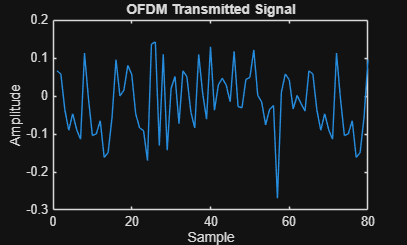

%% tx_ofdm.m
clear; clc; close all;

% Parameters
N = 64;             % OFDM subcarriers
cp = 16;            % cyclic prefix length
M = 4;              % QPSK -> 4 symbols (2 bits per symbol)
k = log2(M);        % bits per symbol

% Generate random bits (column vector)
numBits = N * k;
bits = randi([0 1], numBits, 1);

% Group bits into symbols (rows = symbols)
bits_matrix = reshape(bits, k, []).';   % N x k, each row is one symbol's bits
sym_idx = bi2de(bits_matrix, 'left-msb');  % convert each row to decimal 0..M-1

% QPSK modulation (Gray mapping, pi/4 offset optional)
tx_symbols = pskmod(sym_idx, M, pi/4, 'gray');  % length N

% OFDM: IFFT
ofdm_time = ifft(tx_symbols, N);

% Add cyclic prefix
tx_sig = [ofdm_time(end-cp+1:end); ofdm_time];  % (N+cp) samples

% Save for channel/receiver
save('tx_data.mat', 'bits', 'bits_matrix', 'sym_idx', 'tx_symbols', 'tx_sig', 'N', 'cp', 'M');

% Plot transmit signal
figure; plot(real(tx_sig));
title('OFDM Transmitted Signal'); xlabel('Sample'); ylabel('Amplitude');
% after plotting in tx_ofdm.m
saveas(gcf,'tx_time.png');